# TP 2 : SIFTs and Moravec points

## I. Tests on SIFTs  

SIFT illustrations Results

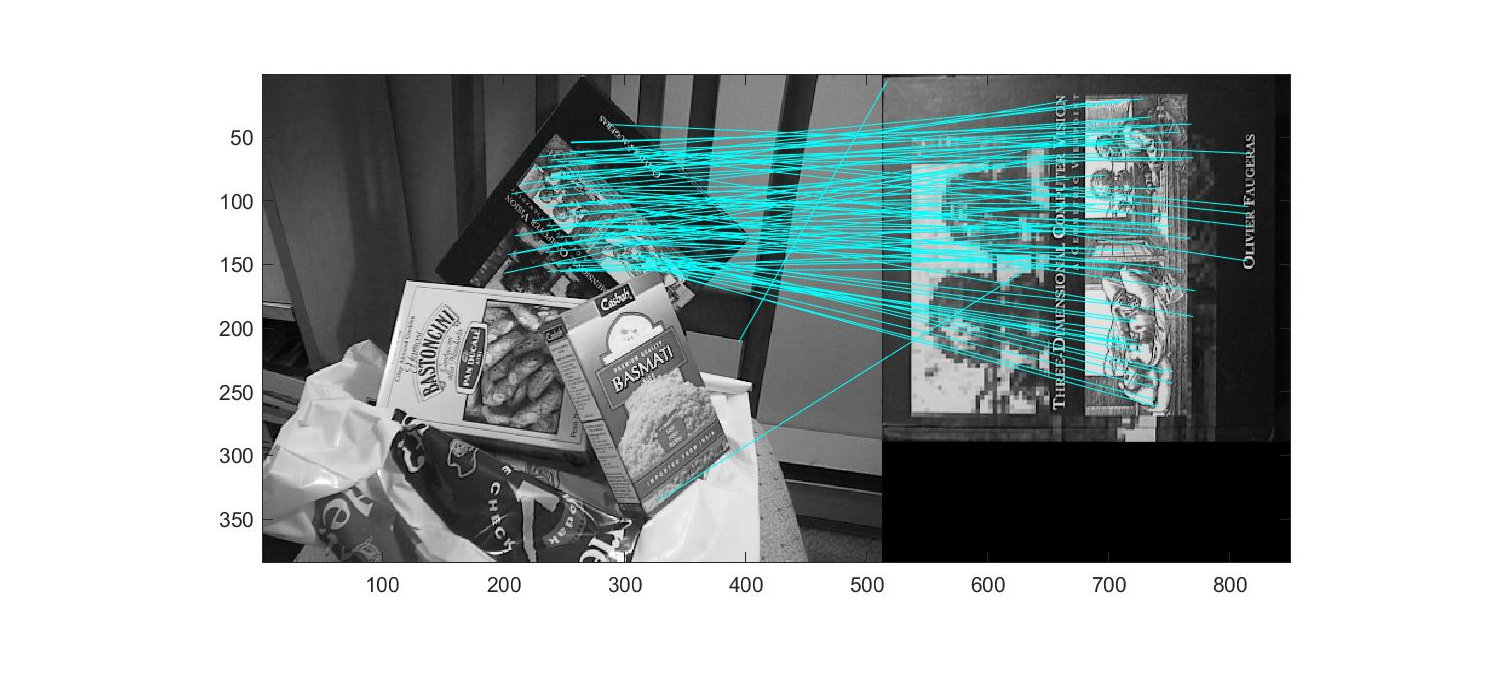

book=imread('siftDemoV4\book.jpg');
box=imread('siftDemoV4\box.jpg');
basmati=imread('siftDemoV4\basmati.jpg');
imshow(book);

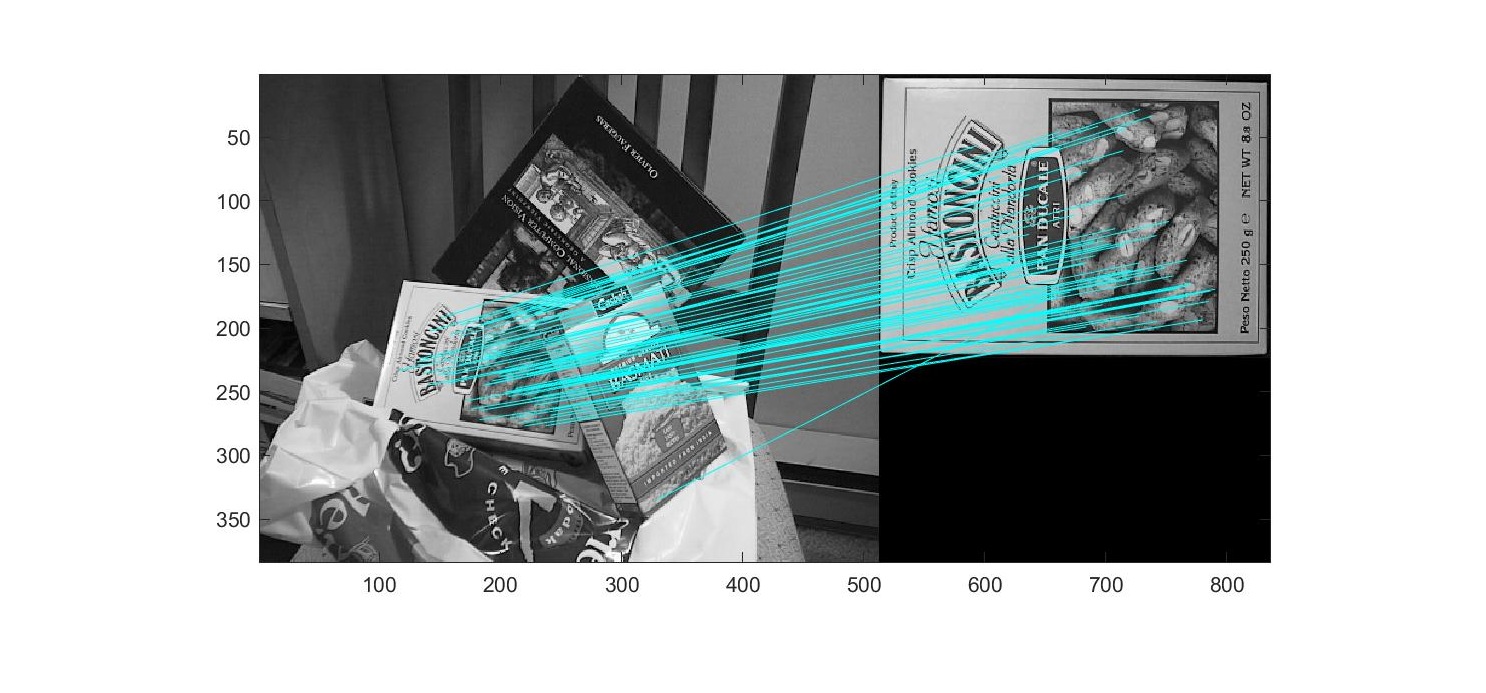

imshow(box);

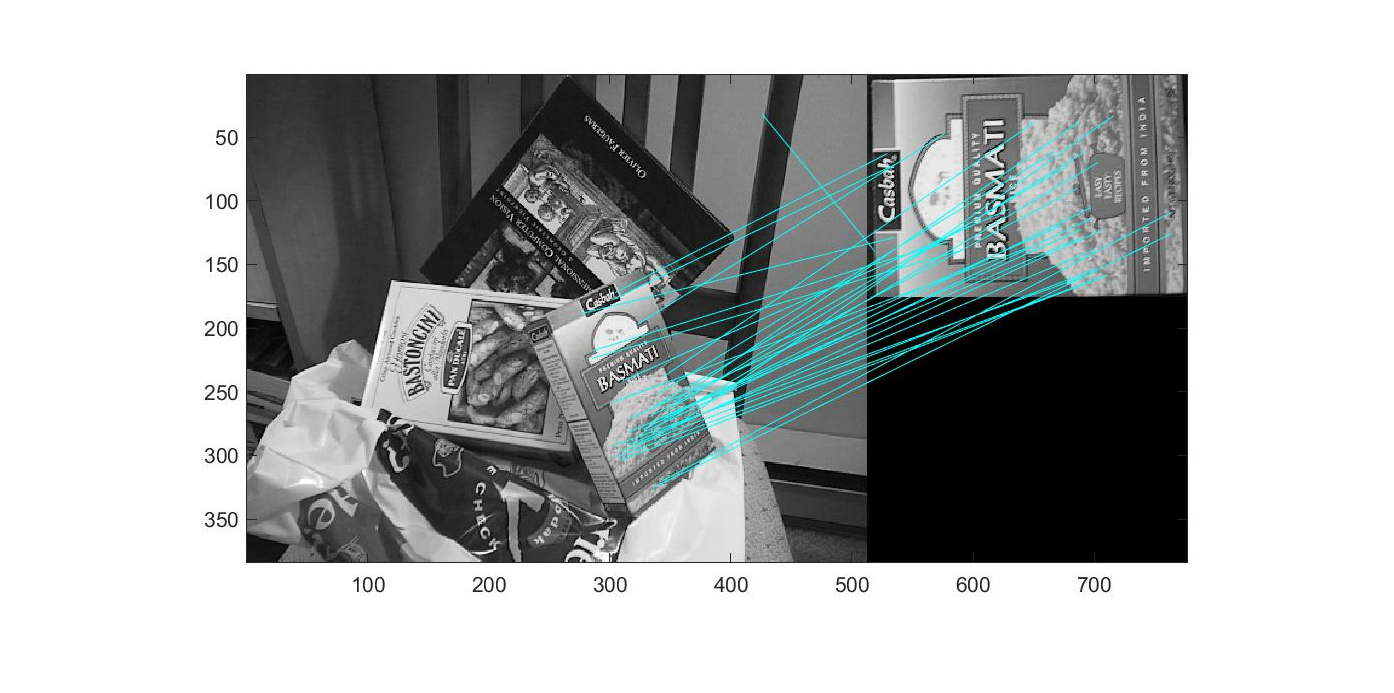

imshow(basmati);

## II. Moravec's points

1.

I1 = imread ("TP02I01.bmp");
w=3;
[a, R] = moravec(I1, w);
nb_keypoint = size(a,1)

nb_keypoint = 99

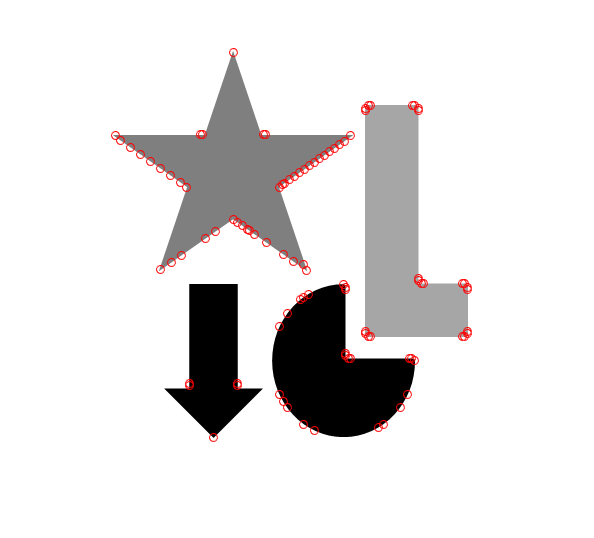

figure(1);
imshow(I1);
hold on
scatter(a(:,1),a(:,2),'r');
hold off


w=11;
[a, R] = moravec(I1, w);
nb_keypoint = size(a,1)

nb_keypoint = 19

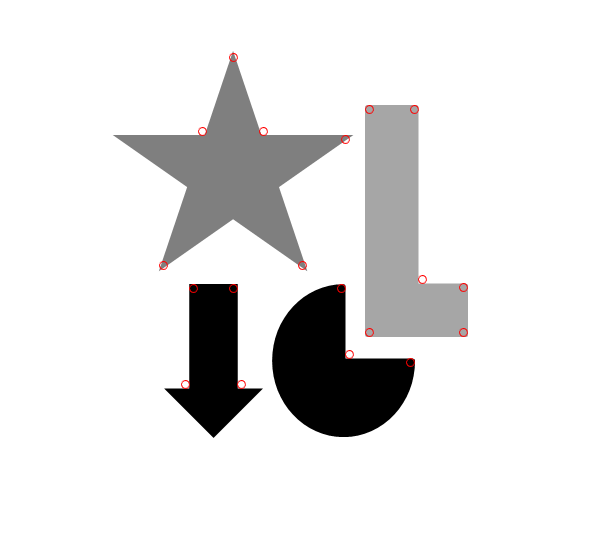

figure(2);
imshow(I1);
hold on
scatter(a(:,1),a(:,2),'r');
hold off


w=25;
[a, R] = moravec(I1, w);
nb_keypoint = size(a,1)

nb_keypoint = 19

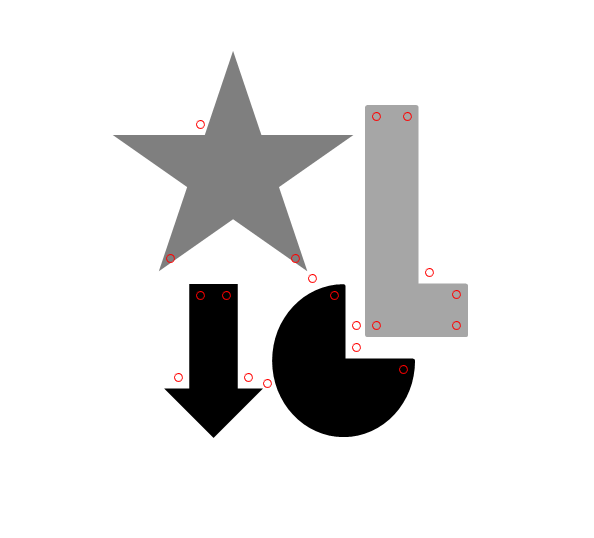

figure(3);
imshow(I1);
hold on
scatter(a(:,1),a(:,2),'r');
hold off

w=11;
[a, R] = moravec(I1, w);


## 3. LBP

descripteur = LBP(I1,a)

descripteur =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


## 4. Matching

I2 = imread ("TP02I02.bmp");
w=11;
[a2, R2] = moravec(I2, w);
nb_keypoint = size(a2,1)

nb_keypoint = 29

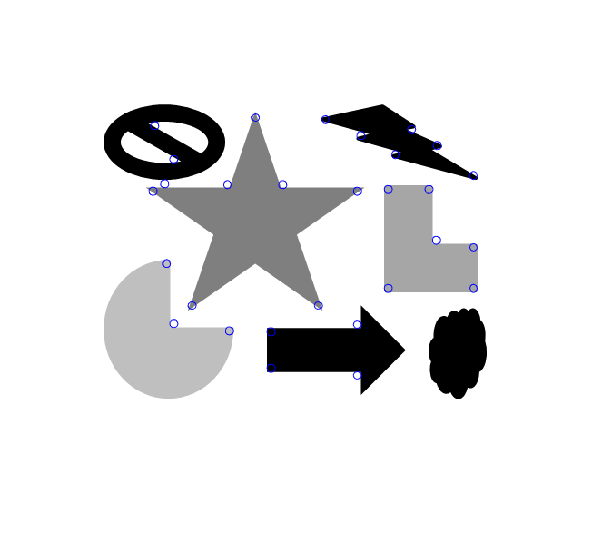

figure(2);
imshow(I2);
hold on
scatter(a2(:,1),a2(:,2),'b');

descripteur2 = LBP(I2,a2);

descripteur2 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     1     1     0     0     1     1     1     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1     1     0     0     0     1     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


D = pdist2(descripteur2,descripteur,'hamming');

D =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.3125    0.3125    0.3125    0.3125    0.3125    0.3125    0.3125    0.3125    0.3125    0.3125    0.3125    0.3125    0.3125    0.3125    0.3125    0.3125    0.3125    0.3125    0.3125
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.1875    0.1875    0.1875    0.1875    0.1875    0.1875    0.1875    0.1875    0.1875    0.1875    0.1875    0.1875    0.1875    0.1875    0.1875    0.1875    0.1875    0.1875    0.1875
         0         0         0         0 

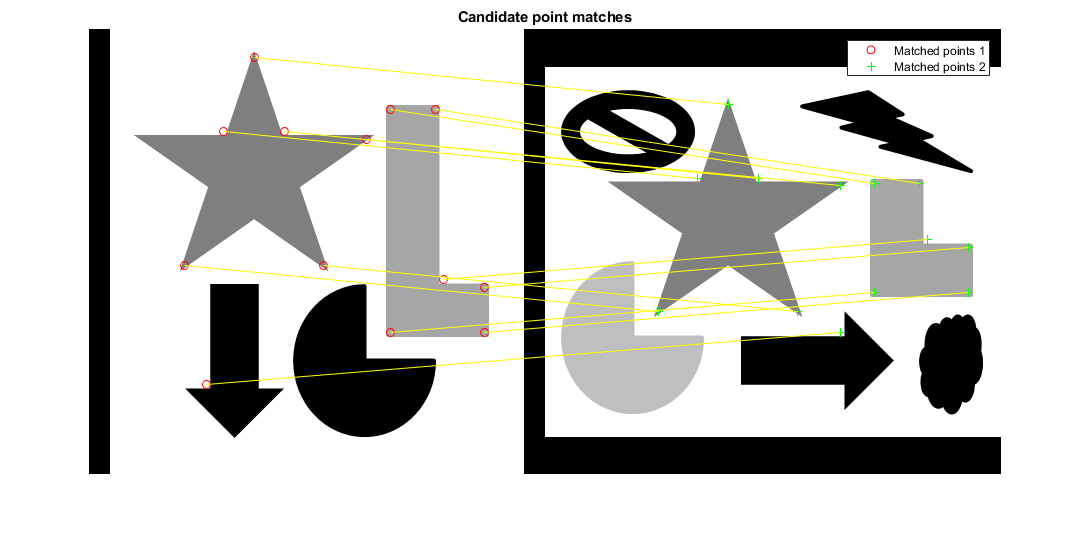


[features1,valid_points1] = extractFeatures(I1,a);
[features2,valid_points2] = extractFeatures(I2,a2);
indexPairs = matchFeatures(features1,features2);
matchedPoints1 = valid_points1(indexPairs(:,1),:);
matchedPoints2 = valid_points2(indexPairs(:,2),:);
figure; 
ax=axes;
showMatchedFeatures(I1,I2,matchedPoints1,matchedPoints2,'montage','Parent',ax);
title(ax, 'Matching');
legend(ax, 'Matched points 1','Matched points 2');